clc,clear,close all
V = 14;
theta = 30;
theta = theta/180*pi;
A = 3;
f = @(x,y) [y(2);
    1/2*V*cos(theta)+3/50*A*sin(y(1)/10)-3/5*y(2)];             % 设置微分方程
a = 0;                          % 区间左端点
b = 50;                          % 区间右端点
h = 0.1;                        % 取点间隔
x = a:h:b;                      % x_i
y0 = [0;0];                       % 设置初始值

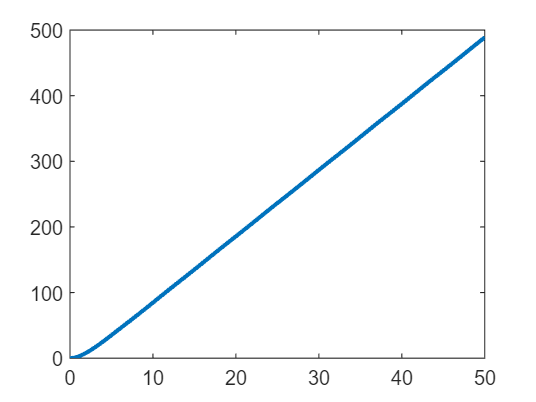

%% 利用龙格库塔法求解微分方程
y = Runge_Kutta2(f,a,b,h,y0);

%% 绘制图像
plot(x,y(1,:),'linewidth',2)